# [Solutions] Time-dependent variational principle (TDVP): 1-site variant

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will implement the 1-site TDVP method for simulating the real-time evolution of one-dimensional quantum states.

## Solution to Exercise (a): Complete the function for 1-site TDVP

The complete version of the function is uploaded as `DMRG/TDVP_1site.m`. Compare with your version!

## Solution to Exercise (b): Compare the accuracy between 1-site TDVP and tDMRG

For this error analysis, we run the tDMRG and 1-site TDVP calculations for two different values of the maximum bond dimension (`Nkeep` = 10, 20) and for two different values of the time step size (`dt` = 1/20, 1/10). We use a separable state, with bond dimension 1, as the initial state for the tDMRG as done in the previous tutorial. On the other hand, we use sparse tensors (mostly filled with zeros, except for one 1 and one $10^{-8}$ per tensor) for the TDVP as in the demonstration for this tutorial.

We first define parameters and operators that are commonly used in both methods.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% time-evolution parameters
tmax = 15; % maximum time
Nkeep = [10 20]; % bond dimensions
dt = [1/20 1/10]; % discrete time step sizes

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% operator to measure magnetization
Sz = S(:,:,2);

And we define the MPO Hamiltonian for the TDVP.

% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
H_TDVP = cell(1,L);
H_TDVP(:) = {Hloc};
H_TDVP{1} = H_TDVP{1}(:,:,end,:); % choose the last components of the left leg
H_TDVP{end} = H_TDVP{end}(:,:,:,1); % choose the first components of the right leg

For the tDMRG, we define a cell array of two-site interaction terms defined as rank-4 tensors.

% nearest-neighbor interaction terms
H_tDMRG = cell(1,L-1);
H_tDMRG(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

Also we define the initial state for the tDMRG as a separable state.

M0_tDMRG = cell(1,L);
for itN = (1:L)
    if itN <= (L/2)
        M0_tDMRG{itN} = permute([1 0],[1 3 2]);
    else
        M0_tDMRG{itN} = permute([0 1],[1 3 2]);
    end
end

On the other hand, we define the initial states for the TDVP calculations inside a for-loop over different values of `Nkeep`, since an initial state consists of large sparse tensors whose sizes are set by `Nkeep`.

v = [1,1e-8]; v = v/norm(v); % to define the initial states for TDVP

% result arrays
Ovals_TDVP = cell(numel(Nkeep),numel(dt));
Ovals_tDMRG = cell(numel(Nkeep),numel(dt));
ts = cell(numel(Nkeep),numel(dt));

for itk = (1:numel(Nkeep))
    % initial state for TDVP
    M0_TDVP = cell(1,L);
    
    for itN = (1:L)
        if itN == 1
            M0_TDVP{itN} = zeros(1,Nkeep(itk),size(I,2));
        elseif itN == L
            M0_TDVP{itN} = zeros(Nkeep(itk),1,size(I,2));
        else
            M0_TDVP{itN} = zeros(Nkeep(itk),Nkeep(itk),size(I,2));
        end
    
        if itN <= (L/2)
            M0_TDVP{itN}(1,1,:) = reshape(v,[1 1 2]);
        else
            M0_TDVP{itN}(1,1,:) = reshape(fliplr(v),[1 1 2]);
        end
    end

    for itt = (1:numel(dt))
        [ts{itk,itt},~,Ovals_TDVP{itk,itt}] = TDVP_1site ( ...
            M0_TDVP,H_TDVP,Sz,Nkeep(itk),dt(itt),tmax);
        [~ ,~,Ovals_tDMRG{itk,itt}] = tDMRG (M0_TDVP, ...
            H_tDMRG,Sz,Nkeep(itk),dt(itt),tmax);
    end
end

I hide the log messages, since they are too long.

To estimate the error of numerical results, we use the exact result for the XY model.

% exact result for different time step grids
Oexact = cell(1,numel(dt)); % exact result, for different time grids

for itt = (1:numel(dt))
    fvals = zeros(numel(ts{1,itt}),L-1);
    for it = (1:size(fvals,2))
        fvals(:,it) = (besselj(it-(L/2),ts{1,itt}(:))).^2;
    end
    fvals = -0.5*fvals;
    
    Oexact{itt} = zeros(numel(ts{1,itt}),L/2);
    for it = (1:(L/2))
        Oexact{itt}(:,it) = sum(fvals(:,(L/2-it+1):(it+L/2-1)),2);
    end
    Oexact{itt} = [-fliplr(Oexact{itt}),Oexact{itt}];
end

Plot the errors.

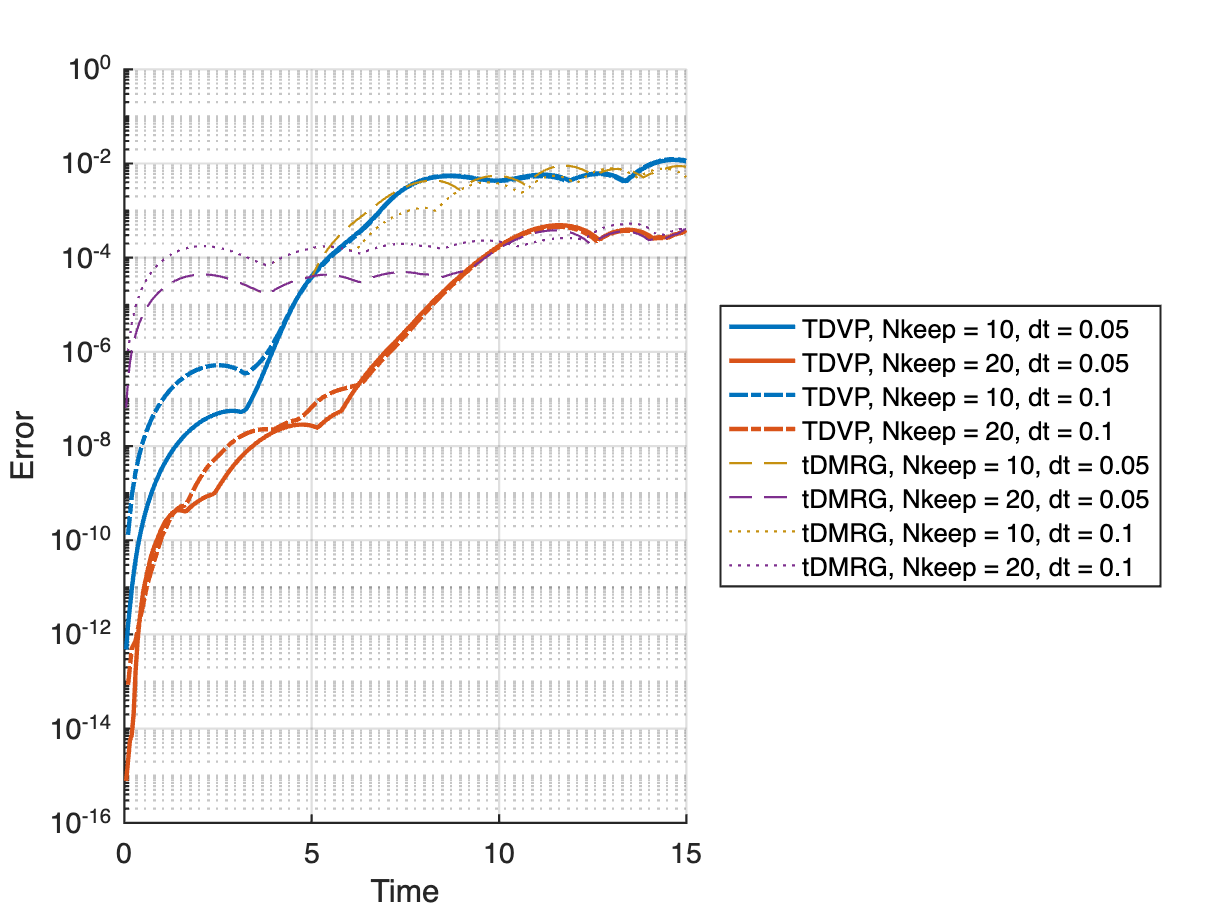

clrs = [0 .447 .741; .85 .325 .098; .773 .565 .061; .494 .184 .556];
lnst = {'-','-.','--',':'};

figure;
legs = cell([size(ts) 2]);
hold on;
for itt = (1:numel(dt))
    for itk = (1:numel(Nkeep))
        plot(ts{itk,itt},max(abs(Ovals_TDVP{itk,itt}-Oexact{1,itt}),[],2), ...
            'LineWidth',2,'Color',clrs(itk,:),'LineStyle',lnst{itt});
        legs{itk,itt,1} = ['TDVP, Nkeep = ',sprintf('%i',Nkeep(itk)), ...
            ', dt = ',sprintf('%.4g',dt(itt))];
    end
end
for itt = (1:numel(dt))
    for itk = (1:numel(Nkeep))
        plot(ts{itk,itt},max(abs(Ovals_tDMRG{itk,itt}-Oexact{1,itt}),[],2), ...
            'LineWidth',1,'Color',clrs(itk+2,:),'LineStyle',lnst{itt+2});
        legs{itk,itt,2} = ['tDMRG, Nkeep = ',sprintf('%i',Nkeep(itk)), ...
            ', dt = ',sprintf('%.4g',dt(itt))];
    end
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('Time');
ylabel('Error');
legend(legs(:),'Location','eastoutside');

We find that the TDVP is more accurate at earlier time steps. As the "runaway time" (when the error due to finite bond dimensions becomes dominant, since the entanglement growth becomes significant; see the solution of the tDMRG tutorial and Sec. IV of Gobert2005 [[D. Gobert, C. Kollath, U. Schollwöck, and G. Schütz, Phys. Rev. E **71**, 036102 (2005)](https://journals.aps.org/pre/abstract/10.1103/PhysRevE.71.036102)] for details.) approaches, the TDVP error increases quickly. And then, after the runaway time, the TDVP and tDMRG show similar sizes of errors, meaning that both methods suffer with finite bond dimensions at later times.